# **Get started!**

#### about the adding path and removing path

addpath(pwd)

datdir = '/Users/byeolkim/Desktop'

addpath(genpath(pwd))

ans = '/Users/byeolkim'

rmpath(genpath(pwd))
savepath

#### Changing current directory

datdir = '/Users/byeolkim/Desktop'
pwd
cd '/Users/byeolkim/Desktop'
cd(datdir)
cd ..

#### Add Comments

When you write code, it is a good practice to add comments that describe the code. Comments allow others to understand your code and can refresh your memory when you return to it later. During program development and testing, you also can use comments to comment out any code that does not need to run.

To add comments to MATLAB code, use the percent (`%`) symbol. Comment lines can appear anywhere in a program file, and you can append comments to the end of a line of code. 

In my computer, keyboard shortcut for add comments is command + / (slash) and for removing comments is command + T. It could be different and you can change it!

addpath(pwd)    % you can add comments  
addpath(genpath(pwd))
rmpath(genpath(pwd))
savepath

#### Useful keyboard shortcuts

- Environment setting                             : command + , (comma)  

- Run the code in the current section     : command + (returns, enter)

- Run the current section and move to the next section : command + shift + (returns, enter)

- Move to the previous section               : command + (up arrow)

- Move to the next section                      : command + (down arrow)

- Abort                                                    : command + C

- Auto indent                                           : command + I                         

- Add comments                                     : command + / (slash)             Ctrl + R 

- Remove comments                              : command + T                        

- Save (save as often as possible!!)       : command + S 

- New script                                            : command + N 

# **Various types of data - Double, Characters**

## **Double**

d_a = 1

d_a = 1

d_b = magic(4)

d_b =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


d_c = zeros(1,2,3)

d_c = d_c(:,:,1) =

     0     0


d_c(:,:,2) =

     0     0


d_c(:,:,3) =

     0     0


whos

  Name      Size             Bytes  Class     Attributes

  d_a       1x1                  8  double              
  d_b       4x4                128  double              
  d_c       1x2x3               48  double              



## Logical function converts numeric values to logicals. 

logical(A) converts input into an array of logical values. Any nonzero element of A is converted to logical `1` (`true`) and zeros are converted to logical `0` (`false`).

l_a = true      % same as logical output 1

l_a = logical
   1


l_b = false     % same as logical output 0

l_b = logical
   0


logical(l_a)

ans = logical
   1


logical(l_b)

ans = logical
   0


logical(3)

ans = logical
   1


logical(0)

ans = logical
   0


logical(d_b)

ans = 4×4 logical 배열
   1   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


d_a == 1

ans = logical
   1


d_a == 3

ans = logical
   0


l_c = d_b < 4

l_c = 4×4 logical 배열
   0   1   1   0
   0   0   0   0
   0   0   0   0
   0   0   0   1


~l_c % logical 'Not' operator

ans = 4×4 logical 배열
   1   0   0   1
   1   1   1   1
   1   1   1   1
   1   1   1   0


## Text in String Arrays

When you are working with text, enclose sequences of characters in double quotes. You can assign text to a variable.

t = "Hello, world";

If the text includes double quotes, use two double quotes within the definition.

q = "Something ""quoted"" and something else."

q = "Something "quoted" and something else."

`t` and `q` are arrays, like all MATLAB variables. Their *class* or data type is `string`.

whos t

  Name      Size            Bytes  Class     Attributes

  t         1x1               158  string              



To add text to the end of a string, use the plus operator, `+`.

f = 71;
c = (f-32)/1.8;
tempText = "Temperature is " + c + "C"

tempText = "Temperature is 21.6667C"

Similar to numeric arrays, string arrays can have multiple elements. Use the `strlength` function to find the length of each string within an array.

A = ["a","bb","ccc"; "dddd","eeeeee","fffffff"]

A = 2×3 string 배열
    "a"       "bb"        "ccc"    
    "dddd"    "eeeeee"    "fffffff"


strlength(A)

ans =      1     2     3
     4     6     7


## **Data in Character Arrays**

Sometimes characters represent data that does not correspond to text, such as a DNA sequence. You can store this type of data in a character array, which has data type `char`. Character arrays use single quotes.

seq = 'GCTAGAATCC';
whos seq

  Name      Size            Bytes  Class    Attributes

  seq       1x10               20  char               



Each element of the array contains a single character.

seq(4)

ans = 'A'

Concatenate character arrays with square brackets, just as you concatenate numeric arrays.

seq2 = [seq 'ATTAGAAACC']

seq2 = 'GCTAGAATCCATTAGAAACC'

Character arrays are common in programs that were written before the introduction of string arrays. All MATLAB functions that accept `string` data also accept `char` data, and vice versa.

# **Various types of data - cell**

A cell array is a data type with indexed data containers called cells. Each cell can contain any type of data. Cell arrays commonly contain pieces of text, combinations of text and numbers from spreadsheets or text files, or numeric arrays of different sizes.

## Create Cell Array

This example shows how to create a cell array using the `{}` operator or the `cell` function.

When you have data to put into a cell array, create the array using the cell array construction operator, `{}`.

myCell = {1, 2, 3;
          'text', rand(5,10,2), {11; 22; 33}}

myCell = 2×3 cell 배열
    {[   1]}    {[          2]}    {[     3]}
    {'text'}    {5×10×2 double}    {3×1 cell}


Like all MATLAB® arrays, cell arrays are rectangular, with the same number of cells in each row. `myCell` is a 2-by-3 cell array.

You also can use the `{}` operator to create an empty 0-by-0 cell array.

C = {}


C =

  0×0 비어 있는 cell 배열



To add values to a cell array over time or in a loop, create an empty `N`-dimensional array using the `cell` function.

emptyCell = cell(3,4,2)

emptyCell = 3×4×2 cell 배열
emptyCell(:,:,1) = 

    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


emptyCell(:,:,2) = 

    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


emptyCell is a 3-by-4-by-2 cell array, where each cell contains an empty array, [].

Change it to 2-by-3 cell array.

emptyCell = cell(2,3);

emptyCell = 3×4×2 cell 배열
emptyCell(:,:,1) = 

    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {[       1]}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


emptyCell(:,:,2) = 

    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


emptyCell{2,1} = 1

emptyCell = 3×4×2 cell 배열
emptyCell(:,:,1) = 

    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {2×2 cell  }    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


emptyCell(:,:,2) = 

    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


emptyCell{1,3} = cell(2,2)

## Cell Indexing with Smooth Parentheses, ()

Create a 2-by-3 cell array of text and numeric data.

C = {'one', 'two', 'three'; 
     1, 2, 3}

C = 2×3 cell 배열
    {'one'}    {'two'}    {'three'}
    {[  1]}    {[  2]}    {[    3]}


There are two ways to refer to the elements of a cell array. Enclose indices in smooth parentheses, `()`, to refer to sets of cells--for example, to define a subset of the array. Enclose indices in curly braces, `{}`, to refer to the text, numbers, or other data within individual cells.Cell array indices in smooth parentheses refer to sets of cells. For example, to create a 2-by-2 cell array that is a subset of `C`, use smooth parentheses.

upperLeft = C(1:2,1:2)

upperLeft = 2×2 cell 배열
    {'one'}    {'two'}
    {[  1]}    {[  2]}


Update sets of cells by replacing them with the same number of cells. For example, replace cells in the first row of `C` with an equivalent-sized (1-by-3) cell array.

C(1,1:3) = {'first','second','third'}

C = 2×3 cell 배열
    {'first'}    {'second'}    {'third'}
    {[    1]}    {[     2]}    {[    3]}


If cells in your array contain numeric data, you can convert the cells to a numeric array using the `cell2mat` function.

numericCells = C(2,1:3)

numericCells = 1×3 cell 배열
    {[1]}    {[2]}    {[3]}


numericVector = cell2mat(numericCells)

numericVector =      1     2     3


`numericCells` is a 1-by-3 cell array, but `numericVector` is a 1-by-3 array of type `double`.

## Content Indexing with Curly Braces, {}

Access the contents of cells--the numbers, text, or other data within the cells--by indexing with curly braces. For example, to access the contents of the last cell of `C`, use curly braces.

last = C{2,3}

last = 3

`last` is a numeric variable of type `double`, because the cell contains a `double` value.

Similarly, you can index with curly braces to replace the contents of a cell.

C{2,3} = 300

C = 2×3 cell 배열
    {'first'}    {'second'}    {'third'}
    {[    1]}    {[     2]}    {[  300]}


You can access the contents of multiple cells by indexing with curly braces. MATLAB® returns the contents of the cells as a *comma-separated list*. Because each cell can contain a different type of data, you cannot assign this list to a single variable. However, you can assign the list to the same number of variables as cells. MATLAB® assigns to the variables in column order.

Assign contents of four cells of `C` to four variables.

[r1c1, r2c1, r1c2, r2c2] = C{1:2,1:2}

r1c1 = 'first'

r2c1 = 1

r1c2 = 'second'

r2c2 = 2

If each cell contains the same type of data, you can create a single variable by applying the array concatenation operator, `[]`, to the comma-separated list.

Concatenate the contents of the second row into a numeric array.

nums = [C{2,:}]

nums =      1     2   300


# **Structure Arrays**

When you have data that you want to organize by name, you can use structures to store it. Structures store data in containers called fields, which you can then access by the names you specify. Use dot notation to create, assign, and access data in structure fields. If the value stored in a field is an array, then you can use array indexing to access elements of the array. When you store multiple structures as a structure array, you can use array indexing and dot notation to access individual structures and their fields.

## Create Scalar Structure

First, create a structure named patient that has fields storing data about a patient. The diagram shows how the structure stores data. A structure like patient is also referred to as a scalar structure because the variable stores one structure.

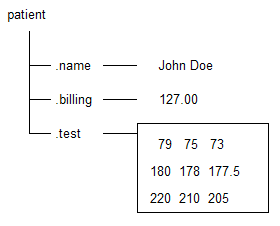

Use dot notation to add the fields name, billing, and test, assigning data to each field. In this example, the syntax patient.name creates both the structure and its first field. The commands that follow add more fields.

patient.name = 'John Doe';
patient.billing = 127;
patient.test = [79 75 73; 180 178 177.5; 220 210 205]

patient = 다음 필드를 포함한 struct :
       name: 'John Doe'
    billing: 127
       test: [3×3 double]


## **Access Values in Fields**

After you create a field, you can keep using dot notation to access and change the value it stores.

For example, change the value of the `billing` field.

patient.billing = 512.00

patient = 다음 필드를 포함한 struct :
       name: 'John Doe'
    billing: 512
       test: [3×3 double]


With dot notation, you also can access the value of any field. For example, make a bar chart of the values in `patient.test`. Add a title with the text in `patient.name`. If a field stores an array, then this syntax returns the whole array.

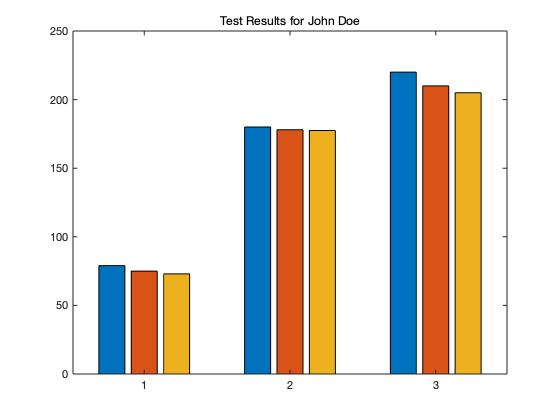

bar(patient.test)
title("Test Results for " + patient.name)

To access part of an array stored in a field, add indices that are appropriate for the size and type of the array. For example, create a bar chart of the data in one column of `patient.test`.

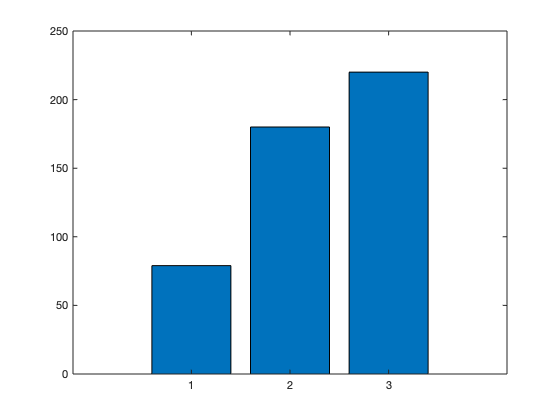

bar(patient.test(:,1))

`fields = fieldnames(`[`S`](https://www.mathworks.com/help/matlab/ref/fieldnames.html#mw_02c445a2-9807-4a4f-a1a2-e21705ebbea9)`)` returns the field names of the structure array `S` in a cell array.

fields = fieldnames(patient)

fields = 3×1 cell 배열
    {'name'   }
    {'billing'}
    {'test'   }


clear fields
clear